**Đặt trục**

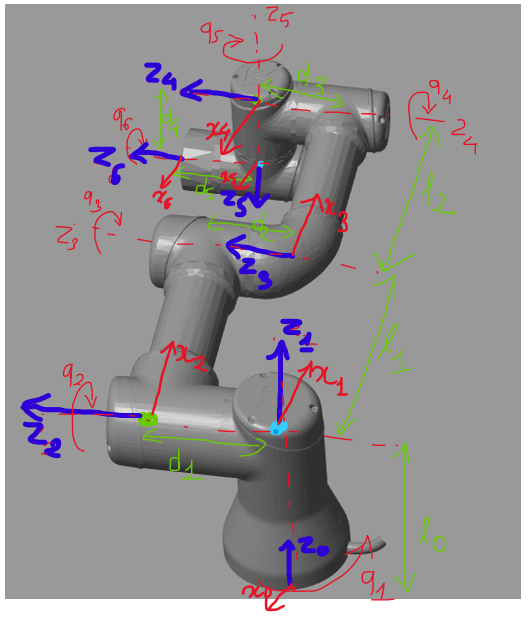

**Bảng MDH**

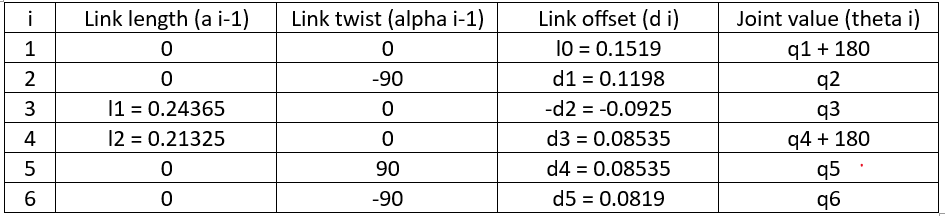

%===============ForwardKinematics==============%
syms theta1 theta2 theta3 theta4 theta5 theta6 %degree
T01 = DH_transform(0, 0, 0.1519, theta1 + 180);
T12 = DH_transform(0, -90, 0.1198 , theta2);
T23 = DH_transform(0.24365, 0, -0.0925, theta3);
T34 = DH_transform(0.21325, 0, 0.08535, theta4 + 180);
T45 = DH_transform(0, 90, 0.08535, theta5);
T56 = DH_transform(0, -90, 0.0819, theta6);

T0_EF = T01*T12*T23*T34*T45*T56


%Lấy điểm end effector
p_ef_x = T0_EF(1,4);
p_ef_y = T0_EF(2,4);
p_ef_z = T0_EF(3,4);

%Đổi về theo radian
syms t1 t2 t3 t4 t5 t6  %t1: theta1
%Tọa độ điểm cuối chuyển theo radian
p_ef_x_short = subs(p_ef_x,[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi])

$$p\_ef\_x\_short = \begin{array}{l} \frac{4873\,\cos\left(t_{2}\right)\,\sigma_{6}}{20000}-\frac{2253\,\sigma_{2}}{20000}-\frac{819\,\sigma_{2}\,\cos\left(t_{5}\right)}{10000}-\frac{819\,\sin\left(t_{5}\right)\,\left(\sigma_{3}\,\sigma_{4}-\sigma_{1}\,\sigma_{5}\right)}{10000}+\frac{1707\,\sigma_{3}\,\sigma_{5}}{20000}+\frac{1707\,\sigma_{1}\,\sigma_{4}}{20000}+\frac{853\,\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)\,\sigma_{6}}{4000}-\frac{853\,\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)\,\sigma_{6}}{4000}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\right)\\ \sigma_{2}=\sin\left(\frac{\pi \,\left(\frac{180\,t_{1}}{\pi }+180\right)}{180}\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\right)\\ \sigma_{4}=\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)\,\sigma_{6}-\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)\,\sigma_{6}\\ \sigma_{5}=\cos\left(t_{2}\right)\,\sin\left(t_{3}\right)\,\sigma_{6}+\cos\left(t_{3}\right)\,\sin\left(t_{2}\right)\,\sigma_{6}\\ \sigma_{6}=\cos\left(\frac{\pi \,\left(\frac{180\,t_{1}}{\pi }+180\right)}{180}\right) \end{array}$$

p_ef_y_short = subs(p_ef_y,[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi])

$$p\_ef\_y\_short = \begin{array}{l} \frac{2253\,\sigma_{3}}{20000}+\frac{1707\,\sigma_{1}\,\sigma_{4}}{20000}+\frac{819\,\cos\left(t_{5}\right)\,\sigma_{3}}{10000}+\frac{4873\,\sigma_{6}\,\cos\left(t_{2}\right)}{20000}+\frac{819\,\sin\left(t_{5}\right)\,\left(\sigma_{1}\,\sigma_{5}-\sigma_{2}\,\sigma_{4}\right)}{10000}+\frac{1707\,\sigma_{2}\,\sigma_{5}}{20000}+\frac{853\,\sigma_{6}\,\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)}{4000}-\frac{853\,\sigma_{6}\,\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)}{4000}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,\left(\frac{180\,t_{1}}{\pi }+180\right)}{180}\right)\\ \sigma_{4}=\sigma_{6}\,\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)-\sigma_{6}\,\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)\\ \sigma_{5}=\sigma_{6}\,\cos\left(t_{2}\right)\,\sin\left(t_{3}\right)+\sigma_{6}\,\cos\left(t_{3}\right)\,\sin\left(t_{2}\right)\\ \sigma_{6}=\sin\left(\frac{\pi \,\left(\frac{180\,t_{1}}{\pi }+180\right)}{180}\right) \end{array}$$

p_ef_z_short = subs(p_ef_z,[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi])

$$p\_ef\_z\_short = \begin{array}{l} \frac{819\,\sin\left(t_{5}\right)\,\left(\sigma_{3}\,\sigma_{1}+\sigma_{4}\,\sigma_{2}\right)}{10000}-\frac{1707\,\sigma_{3}\,\sigma_{2}}{20000}-\frac{853\,\cos\left(t_{2}\right)\,\sin\left(t_{3}\right)}{4000}-\frac{853\,\cos\left(t_{3}\right)\,\sin\left(t_{2}\right)}{4000}-\frac{4873\,\sin\left(t_{2}\right)}{20000}+\frac{1707\,\sigma_{4}\,\sigma_{1}}{20000}+\frac{1519}{10000}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)-\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)\\ \sigma_{2}=\cos\left(t_{2}\right)\,\sin\left(t_{3}\right)+\cos\left(t_{3}\right)\,\sin\left(t_{2}\right)\\ \sigma_{3}=\sin\left(\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\right)\\ \sigma_{4}=\cos\left(\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\right) \end{array}$$


%Ma trận xoay chuyển theo radian
R_0_EF_11_short = subs( T0_EF(1,1),[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi])

$$R\_0\_EF\_11\_short = \begin{array}{l} -\cos\left(t_{6}\right)\,\left(\sin\left(\frac{\pi \,\left(\frac{180\,t_{1}}{\pi }+180\right)}{180}\right)\,\sin\left(t_{5}\right)-\cos\left(t_{5}\right)\,\left(\cos\left(\sigma_{1}\right)\,\sigma_{2}-\sin\left(\sigma_{1}\right)\,\sigma_{3}\right)\right)-\sin\left(t_{6}\right)\,\left(\cos\left(\sigma_{1}\right)\,\sigma_{3}+\sin\left(\sigma_{1}\right)\,\sigma_{2}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\\ \sigma_{2}=\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)\,\sigma_{4}-\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)\,\sigma_{4}\\ \sigma_{3}=\cos\left(t_{2}\right)\,\sin\left(t_{3}\right)\,\sigma_{4}+\cos\left(t_{3}\right)\,\sin\left(t_{2}\right)\,\sigma_{4}\\ \sigma_{4}=\cos\left(\frac{\pi \,\left(\frac{180\,t_{1}}{\pi }+180\right)}{180}\right) \end{array}$$

R_0_EF_12_short = subs( T0_EF(1,2),[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi])

$$R\_0\_EF\_12\_short = \begin{array}{l} \sin\left(t_{6}\right)\,\left(\sin\left(\frac{\pi \,\left(\frac{180\,t_{1}}{\pi }+180\right)}{180}\right)\,\sin\left(t_{5}\right)-\cos\left(t_{5}\right)\,\left(\cos\left(\sigma_{1}\right)\,\sigma_{2}-\sin\left(\sigma_{1}\right)\,\sigma_{3}\right)\right)-\cos\left(t_{6}\right)\,\left(\cos\left(\sigma_{1}\right)\,\sigma_{3}+\sin\left(\sigma_{1}\right)\,\sigma_{2}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\\ \sigma_{2}=\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)\,\sigma_{4}-\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)\,\sigma_{4}\\ \sigma_{3}=\cos\left(t_{2}\right)\,\sin\left(t_{3}\right)\,\sigma_{4}+\cos\left(t_{3}\right)\,\sin\left(t_{2}\right)\,\sigma_{4}\\ \sigma_{4}=\cos\left(\frac{\pi \,\left(\frac{180\,t_{1}}{\pi }+180\right)}{180}\right) \end{array}$$

R_0_EF_13_short = subs( T0_EF(1,3),[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi])

$$R\_0\_EF\_13\_short = \begin{array}{l} -\sin\left(\sigma_{2}\right)\,\cos\left(t_{5}\right)-\sin\left(t_{5}\right)\,\left(\cos\left(\sigma_{1}\right)\,\left(\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)\,\cos\left(\sigma_{2}\right)-\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)\,\cos\left(\sigma_{2}\right)\right)-\sin\left(\sigma_{1}\right)\,\left(\cos\left(t_{2}\right)\,\sin\left(t_{3}\right)\,\cos\left(\sigma_{2}\right)+\cos\left(t_{3}\right)\,\sin\left(t_{2}\right)\,\cos\left(\sigma_{2}\right)\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\\ \sigma_{2}=\frac{\pi \,\left(\frac{180\,t_{1}}{\pi }+180\right)}{180} \end{array}$$


R_0_EF_21_short = subs( T0_EF(2,1),[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi])

$$R\_0\_EF\_21\_short = \begin{array}{l} \cos\left(t_{6}\right)\,\left(\sin\left(t_{5}\right)\,\cos\left(\frac{\pi \,\left(\frac{180\,t_{1}}{\pi }+180\right)}{180}\right)-\cos\left(t_{5}\right)\,\left(\sin\left(\sigma_{1}\right)\,\sigma_{3}-\cos\left(\sigma_{1}\right)\,\sigma_{2}\right)\right)-\sin\left(t_{6}\right)\,\left(\sin\left(\sigma_{1}\right)\,\sigma_{2}+\cos\left(\sigma_{1}\right)\,\sigma_{3}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\\ \sigma_{2}=\sigma_{4}\,\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)-\sigma_{4}\,\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)\\ \sigma_{3}=\sigma_{4}\,\cos\left(t_{2}\right)\,\sin\left(t_{3}\right)+\sigma_{4}\,\cos\left(t_{3}\right)\,\sin\left(t_{2}\right)\\ \sigma_{4}=\sin\left(\frac{\pi \,\left(\frac{180\,t_{1}}{\pi }+180\right)}{180}\right) \end{array}$$

R_0_EF_22_short = subs( T0_EF(2,2),[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi])

$$R\_0\_EF\_22\_short = \begin{array}{l} -\sin\left(t_{6}\right)\,\left(\sin\left(t_{5}\right)\,\cos\left(\frac{\pi \,\left(\frac{180\,t_{1}}{\pi }+180\right)}{180}\right)-\cos\left(t_{5}\right)\,\left(\sin\left(\sigma_{1}\right)\,\sigma_{3}-\cos\left(\sigma_{1}\right)\,\sigma_{2}\right)\right)-\cos\left(t_{6}\right)\,\left(\sin\left(\sigma_{1}\right)\,\sigma_{2}+\cos\left(\sigma_{1}\right)\,\sigma_{3}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\\ \sigma_{2}=\sigma_{4}\,\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)-\sigma_{4}\,\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)\\ \sigma_{3}=\sigma_{4}\,\cos\left(t_{2}\right)\,\sin\left(t_{3}\right)+\sigma_{4}\,\cos\left(t_{3}\right)\,\sin\left(t_{2}\right)\\ \sigma_{4}=\sin\left(\frac{\pi \,\left(\frac{180\,t_{1}}{\pi }+180\right)}{180}\right) \end{array}$$

R_0_EF_23_short = subs( T0_EF(2,3),[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi])

$$R\_0\_EF\_23\_short = \begin{array}{l} \cos\left(t_{5}\right)\,\cos\left(\sigma_{2}\right)+\sin\left(t_{5}\right)\,\left(\sin\left(\sigma_{1}\right)\,\left(\sin\left(\sigma_{2}\right)\,\cos\left(t_{2}\right)\,\sin\left(t_{3}\right)+\sin\left(\sigma_{2}\right)\,\cos\left(t_{3}\right)\,\sin\left(t_{2}\right)\right)-\cos\left(\sigma_{1}\right)\,\left(\sin\left(\sigma_{2}\right)\,\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)-\sin\left(\sigma_{2}\right)\,\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\\ \sigma_{2}=\frac{\pi \,\left(\frac{180\,t_{1}}{\pi }+180\right)}{180} \end{array}$$


R_0_EF_31_short = subs( T0_EF(3,1),[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi])

$$R\_0\_EF\_31\_short = \begin{array}{l} \sin\left(t_{6}\right)\,\left(\sigma_{3}\,\sigma_{2}-\sigma_{4}\,\sigma_{1}\right)-\cos\left(t_{5}\right)\,\cos\left(t_{6}\right)\,\left(\sigma_{3}\,\sigma_{1}+\sigma_{4}\,\sigma_{2}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)-\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)\\ \sigma_{2}=\cos\left(t_{2}\right)\,\sin\left(t_{3}\right)+\cos\left(t_{3}\right)\,\sin\left(t_{2}\right)\\ \sigma_{3}=\sin\left(\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\right)\\ \sigma_{4}=\cos\left(\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\right) \end{array}$$

R_0_EF_32_short = subs( T0_EF(3,2),[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi])

$$R\_0\_EF\_32\_short = \begin{array}{l} \cos\left(t_{6}\right)\,\left(\sigma_{3}\,\sigma_{2}-\sigma_{4}\,\sigma_{1}\right)+\cos\left(t_{5}\right)\,\sin\left(t_{6}\right)\,\left(\sigma_{3}\,\sigma_{1}+\sigma_{4}\,\sigma_{2}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)-\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)\\ \sigma_{2}=\cos\left(t_{2}\right)\,\sin\left(t_{3}\right)+\cos\left(t_{3}\right)\,\sin\left(t_{2}\right)\\ \sigma_{3}=\sin\left(\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\right)\\ \sigma_{4}=\cos\left(\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\right) \end{array}$$

R_0_EF_33_short = subs( T0_EF(3,3),[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi])

$$R\_0\_EF\_33\_short = \sin\left(t_{5}\right)\,\left(\sin\left(\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\right)\,\left(\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)-\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)\right)+\cos\left(\frac{\pi \,\left(\frac{180\,t_{4}}{\pi }+180\right)}{180}\right)\,\left(\cos\left(t_{2}\right)\,\sin\left(t_{3}\right)+\cos\left(t_{3}\right)\,\sin\left(t_{2}\right)\right)\right)$$



%===============Jacobian==============%
    % Linear Jacobian: vận tốc tuyến tính của end effector với tốc độ khớp
 J11 = simplify(diff(p_ef_x_short,t1))

$$J11 = \frac{2253\,\cos\left(t_{1}\right)}{20000}+\frac{819\,\cos\left(t_{1}\right)\,\cos\left(t_{5}\right)}{10000}+\frac{4873\,\cos\left(t_{2}\right)\,\sin\left(t_{1}\right)}{20000}-\frac{853\,\sin\left(t_{1}\right)\,\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)}{4000}+\frac{819\,\cos\left(t_{2}+t_{3}+t_{4}\right)\,\sin\left(t_{1}\right)\,\sin\left(t_{5}\right)}{10000}-\frac{1707\,\cos\left(t_{2}+t_{3}\right)\,\sin\left(t_{1}\right)\,\sin\left(t_{4}\right)}{20000}-\frac{1707\,\sin\left(t_{2}+t_{3}\right)\,\cos\left(t_{4}\right)\,\sin\left(t_{1}\right)}{20000}+\frac{853\,\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)\,\sin\left(t_{1}\right)}{4000}$$

 J12 = simplify(diff(p_ef_x_short,t2))

$$J12 = \frac{\cos\left(t_{1}\right)\,\left(1707\,\cos\left(t_{2}+t_{3}+t_{4}\right)-819\,\cos\left(t_{2}+t_{3}+t_{4}+t_{5}\right)+4265\,\sin\left(t_{2}+t_{3}\right)+4873\,\sin\left(t_{2}\right)+819\,\cos\left(t_{2}+t_{3}+t_{4}-t_{5}\right)\right)}{20000}$$

 J13 = simplify(diff(p_ef_x_short,t3))

$$J13 = \frac{\cos\left(t_{1}\right)\,\left(1707\,\cos\left(t_{2}+t_{3}+t_{4}\right)-819\,\cos\left(t_{2}+t_{3}+t_{4}+t_{5}\right)+4265\,\sin\left(t_{2}+t_{3}\right)+819\,\cos\left(t_{2}+t_{3}+t_{4}-t_{5}\right)\right)}{20000}$$

 J14 = simplify(diff(p_ef_x_short,t4))

$$J14 = \frac{3\,\cos\left(t_{1}\right)\,\left(546\,\sin\left(t_{2}+t_{3}+t_{4}\right)\,\sin\left(t_{5}\right)-569\,\sin\left(t_{2}+t_{3}\right)\,\sin\left(t_{4}\right)+569\,\cos\left(t_{2}+t_{3}\right)\,\cos\left(t_{4}\right)\right)}{20000}$$

 J15 = simplify(diff(p_ef_x_short,t5))

$$J15 = -\frac{819\,\sin\left(t_{1}\right)\,\sin\left(t_{5}\right)}{10000}-\frac{819\,\cos\left(t_{2}+t_{3}+t_{4}\right)\,\cos\left(t_{1}\right)\,\cos\left(t_{5}\right)}{10000}$$

 J16 = simplify(diff(p_ef_x_short,t6))

$$J16 = 0$$


 J21 = simplify(diff(p_ef_y_short,t1))

$$J21 = \frac{2253\,\sin\left(t_{1}\right)}{20000}-\frac{4873\,\cos\left(t_{1}\right)\,\cos\left(t_{2}\right)}{20000}+\frac{819\,\cos\left(t_{5}\right)\,\sin\left(t_{1}\right)}{10000}+\frac{853\,\cos\left(t_{1}\right)\,\sin\left(t_{2}\right)\,\sin\left(t_{3}\right)}{4000}-\frac{819\,\cos\left(t_{2}+t_{3}+t_{4}\right)\,\cos\left(t_{1}\right)\,\sin\left(t_{5}\right)}{10000}+\frac{1707\,\cos\left(t_{2}+t_{3}\right)\,\cos\left(t_{1}\right)\,\sin\left(t_{4}\right)}{20000}+\frac{1707\,\sin\left(t_{2}+t_{3}\right)\,\cos\left(t_{1}\right)\,\cos\left(t_{4}\right)}{20000}-\frac{853\,\cos\left(t_{1}\right)\,\cos\left(t_{2}\right)\,\cos\left(t_{3}\right)}{4000}$$

 J22 = simplify(diff(p_ef_y_short,t2))

$$J22 = \frac{\sin\left(t_{1}\right)\,\left(1707\,\cos\left(t_{2}+t_{3}+t_{4}\right)-819\,\cos\left(t_{2}+t_{3}+t_{4}+t_{5}\right)+4265\,\sin\left(t_{2}+t_{3}\right)+4873\,\sin\left(t_{2}\right)+819\,\cos\left(t_{2}+t_{3}+t_{4}-t_{5}\right)\right)}{20000}$$

 J23 = simplify(diff(p_ef_y_short,t3))

$$J23 = \frac{\sin\left(t_{1}\right)\,\left(1707\,\cos\left(t_{2}+t_{3}+t_{4}\right)-819\,\cos\left(t_{2}+t_{3}+t_{4}+t_{5}\right)+4265\,\sin\left(t_{2}+t_{3}\right)+819\,\cos\left(t_{2}+t_{3}+t_{4}-t_{5}\right)\right)}{20000}$$

 J24 = simplify(diff(p_ef_y_short,t4))

$$J24 = \frac{3\,\sin\left(t_{1}\right)\,\left(546\,\sin\left(t_{2}+t_{3}+t_{4}\right)\,\sin\left(t_{5}\right)-569\,\sin\left(t_{2}+t_{3}\right)\,\sin\left(t_{4}\right)+569\,\cos\left(t_{2}+t_{3}\right)\,\cos\left(t_{4}\right)\right)}{20000}$$

 J25 = simplify(diff(p_ef_y_short,t5))

$$J25 = \frac{819\,\cos\left(t_{1}\right)\,\sin\left(t_{5}\right)}{10000}-\frac{819\,\cos\left(t_{2}+t_{3}+t_{4}\right)\,\cos\left(t_{5}\right)\,\sin\left(t_{1}\right)}{10000}$$

 J26 = simplify(diff(p_ef_y_short,t6))

$$J26 = 0$$


 J31 = simplify(diff(p_ef_z_short,t1))

$$J31 = 0$$

 J32 = simplify(diff(p_ef_z_short,t2))

$$J32 = \sin\left(t_{5}\right)\,\left(\frac{819\,\sin\left(t_{2}+t_{3}\right)\,\sin\left(t_{4}\right)}{10000}-\frac{819\,\cos\left(t_{2}+t_{3}\right)\,\cos\left(t_{4}\right)}{10000}\right)-\frac{4873\,\cos\left(t_{2}\right)}{20000}-\frac{853\,\cos\left(t_{2}+t_{3}\right)}{4000}+\frac{1707\,\cos\left(t_{2}+t_{3}\right)\,\sin\left(t_{4}\right)}{20000}+\frac{1707\,\sin\left(t_{2}+t_{3}\right)\,\cos\left(t_{4}\right)}{20000}$$

 J33 = simplify(diff(p_ef_z_short,t3))

$$J33 = \frac{1707\,\sin\left(t_{2}+t_{3}+t_{4}\right)}{20000}-\frac{853\,\cos\left(t_{2}+t_{3}\right)}{4000}-\frac{819\,\cos\left(t_{2}+t_{3}+t_{4}\right)\,\sin\left(t_{5}\right)}{10000}$$

 J34 = simplify(diff(p_ef_z_short,t4))

$$J34 = \frac{1707\,\sin\left(t_{2}+t_{3}+t_{4}\right)}{20000}-\frac{819\,\cos\left(t_{2}+t_{3}+t_{4}\right)\,\sin\left(t_{5}\right)}{10000}$$

 J35 = simplify(diff(p_ef_z_short,t5))

$$J35 = -\frac{819\,\sin\left(t_{2}+t_{3}+t_{4}\right)\,\cos\left(t_{5}\right)}{10000}$$

 J36 = simplify(diff(p_ef_z_short,t6))

$$J36 = 0$$



    % Angular Jacobian: vận tốc góc của end effector với tốc độ khớp
T01_short = subs(T01,[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi]);
J41 = T01_short(1,3) %lấy cột 3 (trục z) của T01 thành cột 1 của Jw khớp 1

$$J41 = 0$$

J51 = T01_short(2,3)

$$J51 = 0$$

J61 = T01_short(3,3)

$$J61 = 1$$


T02 = T01*T12; %ma trận từ gốc đến khớp 2 (khớp 2 so với gốc)
T02_short = subs(T02,[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi]);
J42 = simplify(T02_short(1,3)) %vector z của khớp 2 trong hệ gốc.

$$J42 = \sin\left(t_{1}\right)$$

J52 = simplify(T02_short(2,3))

$$J52 = -\cos\left(t_{1}\right)$$

J62 = simplify(T02_short(3,3))

$$J62 = 0$$


T03 = T02*T23;
T03_short = subs(T03,[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi]);
J43 = simplify(T03_short(1,3))

$$J43 = \sin\left(t_{1}\right)$$

J53 = simplify(T03_short(2,3))

$$J53 = -\cos\left(t_{1}\right)$$

J63 = simplify(T03_short(3,3))

$$J63 = 0$$


T04 = T03*T34;
T04_short = subs(T04,[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi]);
J44 = simplify(T04_short(1,3))

$$J44 = \sin\left(t_{1}\right)$$

J54 = simplify(T04_short(2,3))

$$J54 = -\cos\left(t_{1}\right)$$

J64 = simplify(T04_short(3,3))

$$J64 = 0$$


T05 = T04*T45;
T05_short = subs(T05,[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi]);
J45 = simplify(T05_short(1,3))

$$J45 = \sin\left(t_{2}+t_{3}+t_{4}\right)\,\cos\left(t_{1}\right)$$

J55 = simplify(T05_short(2,3))

$$J55 = \sin\left(t_{2}+t_{3}+t_{4}\right)\,\sin\left(t_{1}\right)$$

J65 = simplify(T05_short(3,3))

$$J65 = -\cos\left(t_{2}+t_{3}+t_{4}\right)$$


T06 = T05*T56;
T06_short = subs(T06,[theta1 theta2 theta3 theta4 theta5 theta6], [t1*180/pi t2*180/pi t3*180/pi t4*180/pi t5*180/pi t6*180/pi]);
J46 = simplify(T06_short(1,3))

$$J46 = \cos\left(t_{5}\right)\,\sin\left(t_{1}\right)-\cos\left(t_{2}+t_{3}+t_{4}\right)\,\cos\left(t_{1}\right)\,\sin\left(t_{5}\right)$$

J56 = simplify(T06_short(2,3))

$$J56 = -\cos\left(t_{1}\right)\,\cos\left(t_{5}\right)-\cos\left(t_{2}+t_{3}+t_{4}\right)\,\sin\left(t_{1}\right)\,\sin\left(t_{5}\right)$$

J66 = simplify(T06_short(3,3))

$$J66 = -\sin\left(t_{2}+t_{3}+t_{4}\right)\,\sin\left(t_{5}\right)$$


J = [ J11, J12, J13, J14, J15, J16;
      J21, J22, J23, J24, J25, J26;s
      J31, J32, J33, J34, J35, J36;
      J41, J42, J43, J44, J45, J46;
      J51, J52, J53, J54, J55, J56;
      J61, J62, J63, J64, J65, J66];
